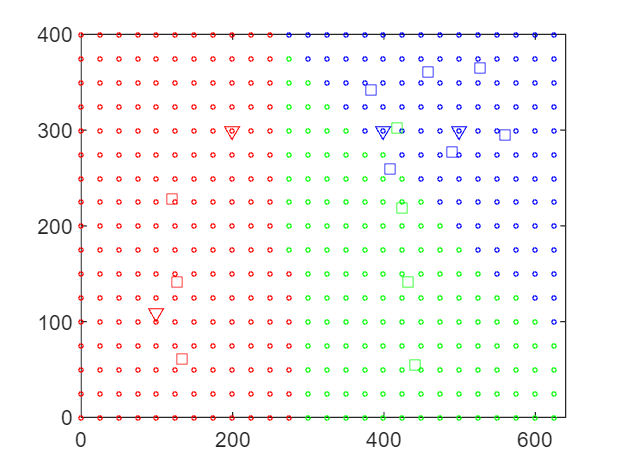


%%---------------PLOT TEST RESULTS-----------------
%prepare table with only test_features
test_features = test_table(:,{'x','y'});

%predict test_results
test_results = trainedModel.predictFcn(test_features);

my_plot(test_features,test_results, 'o', 2);

hold("on")


%%---------------PLOT TRAIN DATA-----------------
%prepare tables with train_features and train_results
train_features = train_table(:,{'x','y'});
train_results = table2array( train_table(:,{'label'}));

my_plot(train_features,train_results, 's', 6);


%%---------------PLOT PREDICTIONS-----------------
%prepare table with only predict_features
predict_features = predict_table(:,{'x','y'});

%predict test_results
predict_results = trainedModel.predictFcn(predict_features);

my_plot(predict_features,predict_results, 'v', 6);

hold("off")

function p = my_plot(features, results, sym, size)
    FEATURE_A = true;
    
    if FEATURE_A
        p = gscatter(features.x,features.y,results,['r','g','b'],sym,size,'off');
        axis([0,640,0,400])
    else
        %setup colormap
        my_red = [1 0 0];
        my_green = [0 1 0];
        my_blue = [0 0 1];
        %setup colors for predictions
        colors = ones(3,height(results));
        for i=(1:height(results))
            switch results(i)
                case 'C'
                    colors(:,i) = my_red;
                case 'D'
                    colors(:,i) = my_green;
                case 'E'
                    colors(:,i) = my_blue;
            end
        end
    
        p = scatter(features.x,features.y,size*6,colors',sym);
    end
end